# Aerodynamic Analysis using XFLR5

## Data Upload

Here we are going to import all of the necessary data we may need. To make variables and data accessible in MATLAB we are going to import and open the `.mat` workspace files.


XFLR5_output = "C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\output.txt";
[aero, geom] = parseXFLR5(XFLR5_output);
fprintf('=== Operating Point ===\n')

=== Operating Point ===


fprintf('  V     = %.3f m/s\n',  aero.V)

  V     = 35.063 m/s


fprintf('  alpha = %.3f deg\n',  aero.alpha)

  alpha = -1.410 deg


fprintf('  CL    = %.5f\n',      aero.CL)

  CL    = 0.12502


fprintf('  Cd    = %.5f\n',      aero.CD)

  Cd    = 0.01305


## Longitudonal Stability

There are two types of stability modes: longitudonal, which focuses on the pitch of the aircraft, and lateral, which accounts for yaw and roll. What do we mean by mode? Modes are natural motions the aircraft can go through during flight. For example, if you push a swing it will move up and down until settling down; that's one mode. Planes have six! How we derive these for an aircraft is a long and arduous proces, but what matters to us is whether or not they're stable. Imagine if your friend pushed you on a swing and you started gaining more and more speed until eventually the swing just broke. Yep. That's not good for planes either.

To visualize modes, we plot the eigenvalues calculated in XFLR5. Generate the plots below to illustrate the modes for your plane!

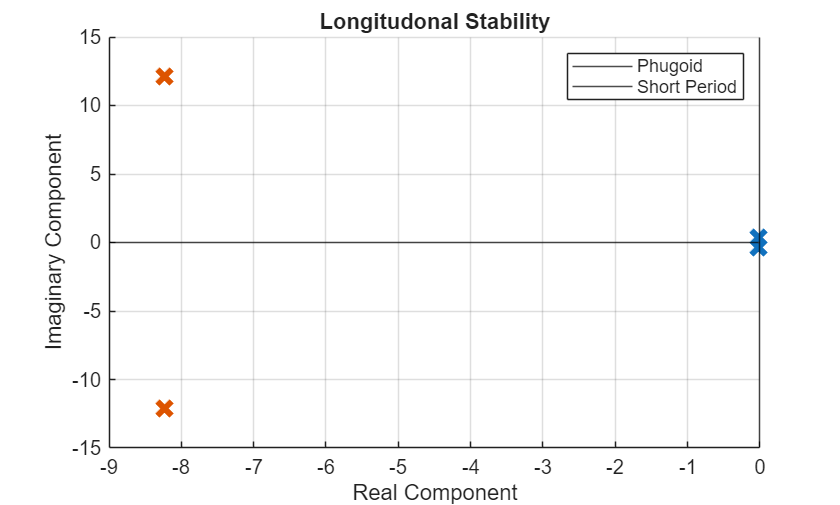

 
% Logitudonal plot setup
figure;
hold on;
xlabel('Real Component')
ylabel('Imaginary Component')
title('Longitudonal Stability')
yline(0, 'k')
xline(0, 'k')
grid on;

% Phugoid
omega = aero.modes.Phugoid.omega;
sigma = aero.modes.Phugoid.sigma;

if (abs(omega) > 0.01)
    plot([sigma, sigma], [omega, -omega], 'x', MarkerSize=10, LineWidth=3)
else
    plot(sigma, omega, 'x', MarkerSize=10, LineWidth=3)
end

% Short period
omega = aero.modes.ShortPeriod.omega;
sigma = aero.modes.ShortPeriod.sigma;

if (abs(omega) > 0.01)
    plot([sigma, sigma], [omega, -omega], 'x', MarkerSize=10, LineWidth=3)
else
    plot(sigma, omega, 'x', MarkerSize=10, LineWidth=3)
end

legend('Phugoid', 'Short Period');
hold off;

## Lateral Stability

In the lateral plots, you'll notice that some modes only have one eigenvalue displayed - they are only real. If you've suffered through PHYS 2214 Waves, you'll recall that means these values do not oscillate and either exponentially decay or grow. It's in this mode we're most likely to see an instability in the dutch roll mode! Zoom in on the origin to see if it is in the positive x-domain.

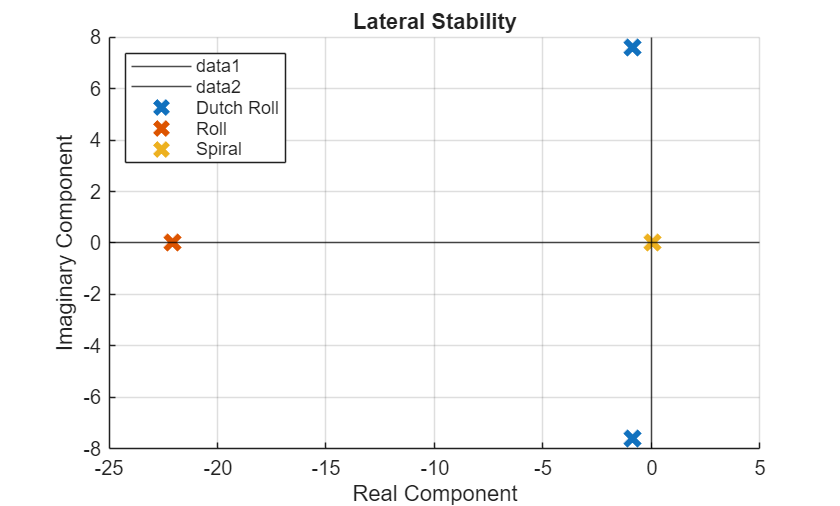

 
%Lateral plot setup
figure;
hold on;
xlabel('Real Component')
ylabel('Imaginary Component')
title('Lateral Stability')
yline(0, 'k')
xline(0, 'k')
grid on;

% Dutch roll
omega = aero.modes.DutchRoll.omega;
sigma = aero.modes.DutchRoll.sigma;

if (abs(omega) > 0.01)
    plot([sigma, sigma], [omega, -omega], 'x', MarkerSize=10, LineWidth=3, DisplayName='Dutch Roll')
else
    plot(sigma, omega, 'x', MarkerSize=10, LineWidth=3, DisplayName='Dutch Roll')
end

% Roll
omega = aero.modes.Roll.omega;
sigma = aero.modes.Roll.sigma;

if (abs(omega) > 0.01)
    plot([sigma, sigma], [omega, -omega], 'x', MarkerSize=10, LineWidth=3, DisplayName='Roll')
else
    plot(sigma, omega, 'x', MarkerSize=10, LineWidth=3, DisplayName='Roll')
end

% Spiral
omega = aero.modes.Spiral.omega;
sigma = aero.modes.Spiral.sigma;

if (abs(omega) > 0.01)
    plot([sigma, sigma], [omega, -omega], 'x', MarkerSize=10, LineWidth=3, DisplayName='Spiral')
else
    plot(sigma, omega, 'x', MarkerSize=10, LineWidth=3, DisplayName='Spiral')
end

legend(Location='northwest');
hold off;

## Doubling Times

One other consideration is the doubling time. If a mode is unstable, we want to measure how long it takes for the instabilities to grow. If they grow very slowly, that's okay. Mitch can just fix it in flight. If it doubles much quicker than a reactio time can allow, that's when we have problems.

%% Doubling Times
mode_names = {'Phugoid', 'ShortPeriod', 'DutchRoll', 'Roll', 'Spiral'};

% Collect only unstable modes (finite doubling time)
unstable_names = {};
unstable_t2    = [];

for k = 1:numel(mode_names)
    m = aero.modes.(mode_names{k});
    if isfinite(m.t2)
        fprintf('Mode: %-12s  t2 = %.3f s\n', mode_names{k}, m.t2);
        unstable_names{end+1} = mode_names{k};
        unstable_t2(end+1)    = m.t2;
    end
end

Mode: Spiral        t2 = 15.807 s


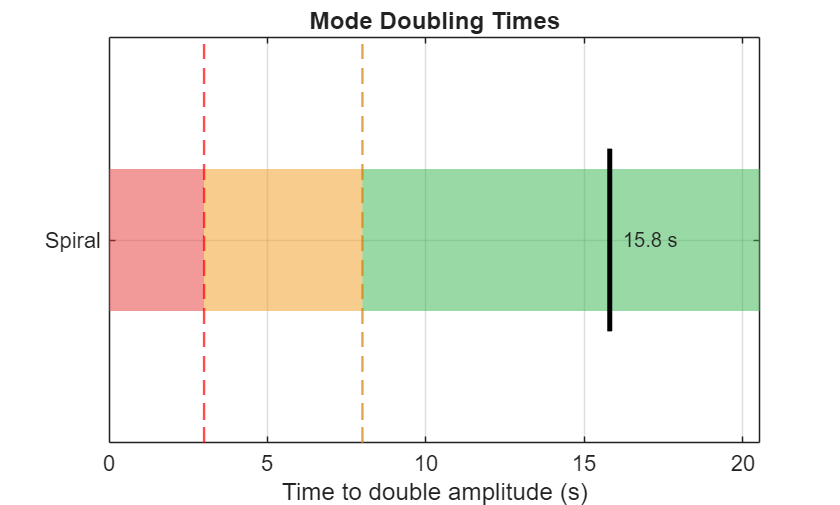


if isempty(unstable_names)
    fprintf('All modes are stable — no doubling times to report.\n')
end

% ── Doubling time bar chart ───────────────────────────────────────────────
if ~isempty(unstable_names)

    figure;
    hold on;
    title('Mode Doubling Times')
    xlabel('Time to double amplitude (s)')

    x_max = max(max(unstable_t2) * 1.3, 12);
    bar_h = 0.35;

    for k = 1:numel(unstable_names)
        t2 = unstable_t2(k);
        y  = [k-bar_h/2, k-bar_h/2, k+bar_h/2, k+bar_h/2];

        patch([0, min(3,x_max), min(3,x_max), 0], y, ...
              [0.90 0.20 0.20], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        if x_max > 3
            patch([3, min(8,x_max), min(8,x_max), 3], y, ...
                  [0.95 0.60 0.10], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end
        if x_max > 8
            patch([8, x_max, x_max, 8], y, ...
                  [0.20 0.70 0.30], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end

        plot([t2 t2], [k-bar_h/2-0.05, k+bar_h/2+0.05], ...
             'k-', 'LineWidth', 2.5, 'HandleVisibility', 'off')

        text(t2 + x_max*0.02, k, sprintf('%.1f s', t2), ...
             'VerticalAlignment', 'middle', 'FontSize', 10)
    end

    xline(3, 'r--', 'LineWidth', 1.2, 'HandleVisibility', 'off')
    xline(8, '--', 'Color', [0.85 0.50 0.0], 'LineWidth', 1.2, 'HandleVisibility', 'off')

    set(gca, 'YTick', 1:numel(unstable_names), ...
             'YTickLabel', unstable_names, 'FontSize', 11)
    xlim([0 x_max])
    ylim([0.5, numel(unstable_names) + 0.5])
    grid on; box on;
    hold off;

end

## Polars

From XFLR5 we can also get the lift and drag we'd expect at different angles of attack. From the